# Capstone Code

After running the code below, histogram plots will appear. 

In the command window, typing in 

AllId1 - Gives a list of all the IDs/ people found in box 1. 

AllId2 - Same but for box 2.

AllHeight1 or AllSpeed1 or AllShoulderWidth1 - Gives a matrix where each column is a different person with their ID at the first row and their respective heights/speed/shoulder width over time in the following rows for box 1. (72 people total in box 1 so 72 columns)

AllHeight2 or AllSpeed2 or AllShoulderWidth2 - Same but for box 2. (95 people total in box 2 so 95 columns)

HeightAverage1 or SpeedAverage1 or ShoulderWidthAverage1 - Gives average height/speed/shoulder width of each ID/ person seen in box 1. This corresponds with "AllId1".

HeightAverage2 or SpeedAverage2 or ShoulderWidthAverage2 - Same but for box 2. This corresponds with "AllId2".

## Storing pedestrian data in arrays for box 1 and 2

close all
clear all

% baginfo = rosbag('2022-08-29-21-10-20.bag');
baginfo = rosbag('2022-08-29-21-28-22.bag');

startPoint1 = 1200;
endPoint1 = 1800;
  
startPoint2 = 1290;
endPoint2 = 1890;

numstruct = 45;

bSel1 = select(baginfo, 'Topic','/box1/simple_tracker/tracker_data');
bSel2 = select(baginfo,'Topic','/box2/simple_tracker/tracker_data');
box1data = readMessages(bSel1,'DataFormat','struct');
box2data = readMessages(bSel2,'DataFormat','struct');

Person1.Height = [];
Person1.Vx = [];
Person1.Id = [];
Person1.Time = [];
Person1.Sec = [];
Person1.NSec = [];
Person1.ShoulderWidth = [];
Person1.Speed = [];
Person1.Px = [];
Person1.Py = [];
Person1.Pz = [];
Person1.Po = [];
Person1.VelDirection = [];

Person2.Height = [];
Person2.Vx = [];
Person2.Id = [];
Person2.Time = [];
Person2.Sec = [];
Person2.NSec = [];
Person2.ShoulderWidth = [];
Person2.Speed = [];
Person2.Px = [];
Person2.Py = [];
Person2.Pz = [];
Person2.Po = [];
Person2.VelDirection = [];

for i = startPoint1:1:endPoint1
    for x = 1:1:numel(box1data{i}.Persons)
%         rosShowDetails(box1data{i})
        Person1.Id(end+1) = box1data{i}.Persons(x).Id;
        Person1.Height(end+1) = box1data{i}.Persons(x).Pz;
        Person1.ShoulderWidth(end+1) = box1data{i}.Persons(x).FeatureVec;
        Person1.Speed(end+1) = sqrt((box1data{i}.Persons(x).Vx)^2 + (box1data{i}.Persons(x).Vy)^2); 
        Person1.Time(end+1) = int64(box1data{i}.Header.Stamp.Sec + box1data{i}.Header.Stamp.Nsec*1e-9);
        Person1.Px(end+1) = box1data{i}.Persons(x).Px;
        Person1.Py(end+1) = box1data{i}.Persons(x).Py;
        Person1.Pz(end+1) = box1data{i}.Persons(x).Pz;
        Person1.Po(end+1) = box1data{i}.Persons(x).Po;
        Person1.VelDirection(end+1) = atan(box1data{i}.Persons(x).Vy/ box1data{i}.Persons(x).Vx);
%         Person1.Time(end+1) = x;
    end
end

for i = startPoint2:1:endPoint2
    for x = 1:1:numel(box2data{i}.Persons)
        Person2.Id(end+1) = box2data{i}.Persons(x).Id;
        Person2.Height(end+1) = box2data{i}.Persons(x).Pz;
        Person2.ShoulderWidth(end+1) = box2data{i}.Persons(x).FeatureVec;
        Person2.Speed(end+1) = sqrt((box2data{i}.Persons(x).Vx)^2 + (box2data{i}.Persons(x).Vy)^2);
        Person2.Px(end+1) = box2data{i}.Persons(x).Px;
        Person2.Py(end+1) = box2data{i}.Persons(x).Py;
        Person2.Pz(end+1) = box2data{i}.Persons(x).Pz;
        Person2.Po(end+1) = box2data{i}.Persons(x).Po;
        Person2.VelDirection(end+1) = atan(box2data{i}.Persons(x).Vy/ box2data{i}.Persons(x).Vx);
    end
end

## Storing all ID values in arrays

AllId1 = [-1];
for i = 2:1:numel(Person1.Id)
    if (Person1.Id(i) ~= AllId1(:,:))
        AllId1(end+1) = Person1.Id(i);
    end
end
AllId1(1) = [];

AllId2 = [-1];
for i = 2:1:numel(Person2.Id)
    if (Person2.Id(i) ~= AllId2(:,:))
        AllId2(end+1) = Person2.Id(i);
    end
end
AllId2(1) = [];

## Creating ID correspondence

AllId1Correspondence = [1 2 3 4 5 6 7 8 9 10 11];
% 
% AllId2Correspondence = [1 3 2 4 5 6 7 9 8 12 10 13 11];

AllId2Correspondence = [1 3 2 4 5 6 7 9 8  10  11];

## Sorting and plotting pedestrian heights by ID

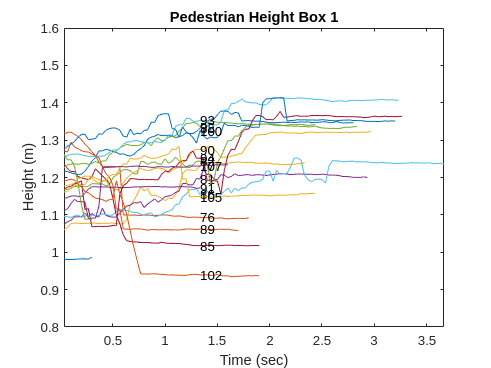

AllHeight1 = zeros(2000,numel(AllId1));

p = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r), Person1.Id(i)))
            AllHeight1(p,r) = Person1.Height(i);
            p = p+1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        p = 1;
    end
end

AllHeight1 = cat(1,AllId1,AllHeight1);

AllHeight2 = zeros(1000,numel(AllId2));

u = 1;

for z = 1:1:numel(AllId2)
    for v = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,z), Person2.Id(v)))
            AllHeight2(u,z) = Person2.Height(v);
            u = u+1;
        end
    end
    if (isequal(v,numel(Person2.Id)))
        u = 1;
    end
end

AllHeight2 = cat(1,AllId2,AllHeight2);


for i = length(AllHeight1):-1:1
    if (AllHeight1(i,:) == 0)
        AllHeight1(i,:) = [];
    end
end

for i = length(AllHeight2):-1:1
    if (AllHeight2(i,:) == 0)
        AllHeight2(i,:) = [];
    end
end


% Deleting anyone with less than 40 structs or 1.33 seconds (different per bag)

% heightcounter1 = 0;
% for i = width(AllHeight1):-1:1
%     for x = 2:1:length(AllHeight1)
%         if (AllHeight1(x,i) > 0)
%         heightcounter1 = heightcounter1 + 1;
%         end
%     end
%     if (heightcounter1 < numstruct)
%         AllHeight1(:,i) = [];
%         AllId1(:,i) = [];
%     end
%     heightcounter1 = 0;
% end
% 
% heightcounter2 = 0;
% for i = width(AllHeight2):-1:1
%     for x = 2:1:length(AllHeight2)
%         if (AllHeight2(x,i) > 0)
%         heightcounter2 = heightcounter2 + 1;
%         end
%     end
%     if (heightcounter2 < numstruct)
%         AllHeight2(:,i) = [];
%         AllId2(:,i) = [];
%     end
%     heightcounter2 = 0;
% end


temparray1 = [];
temptime = (1:(numel(AllHeight1(:,1))-1));
temptime = temptime/30;

for i = 1:1:width(AllHeight1)
    str = string(AllId1(i));
    for x = 2:1:length(AllHeight1)
        temparray1(end+1) = AllHeight1(x,i);
    end

    y=temparray1;
    y(y==0)=nan;

    figure(1);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Height Box 1');
    xlim([1/30 (numel(AllHeight1(:,1))-1)/30]);
    ylim([0.8 1.6]);
    hold on

    temparray1 = [];
end

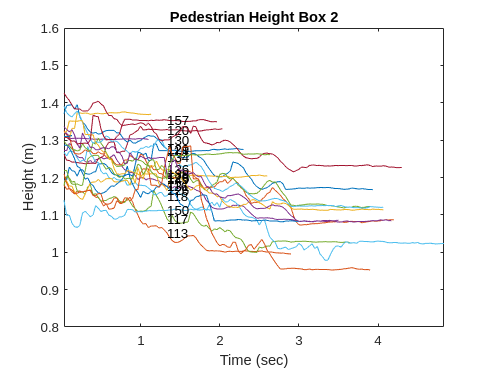




temparray2 = [];
temptime2 = (1:numel(AllHeight2(:,1))-1);
temptime2 = temptime2/30;

for i = 1:1:width(AllHeight2)
    str = string(AllId2(i));
    for x = 2:1:length(AllHeight2)
        temparray2(end+1) = AllHeight2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(2);
    plot(temptime2,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Height Box 2');
    xlim([1/30 (numel(AllHeight2(:,1))-1)/30]);
    ylim([0.8 1.6]);
    hold on;

    temparray2 = [];
end

## Sorting and plotting pedestrian shoulderwidth by ID

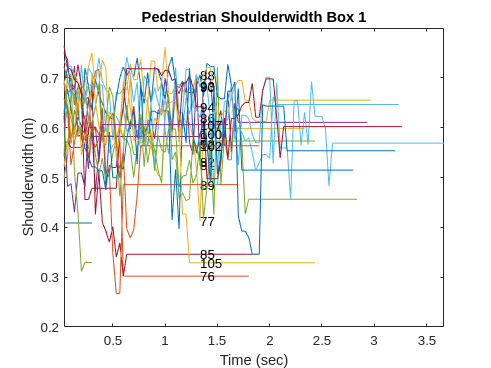

AllShoulderWidth1 = zeros(1000,numel(AllId1));
a = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r), Person1.Id(i)))
            AllShoulderWidth1(a,r) = Person1.ShoulderWidth(i);
            a = a+1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        a = 1;
    end
end

AllShoulderWidth1 = cat(1,AllId1,AllShoulderWidth1);

AllShoulderWidth2 = zeros(70,numel(AllId2));
u = 1;

for z = 1:1:numel(AllId2)
    for v = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,z), Person2.Id(v)))
            AllShoulderWidth2(u,z) = Person2.ShoulderWidth(v);
            u = u+1;
        end
    end
    if (isequal(v,numel(Person2.Id)))
        u = 1;
    end
end

AllShoulderWidth2 = cat(1,AllId2,AllShoulderWidth2);


for i = length(AllShoulderWidth1):-1:1
    if (AllShoulderWidth1(i,:) == 0)
        AllShoulderWidth1(i,:) = [];
    end
end

for i = length(AllShoulderWidth2):-1:1
    if (AllShoulderWidth2(i,:) == 0)
        AllShoulderWidth2(i,:) = [];
    end
end







% Deleting anyone with less than 40 structs or 1.33 seconds (different per bag)

% shouldercounter1 = 0;
% for i = width(AllShoulderWidth1):-1:1
%     for x = 2:1:length(AllShoulderWidth1)
%         if (AllShoulderWidth1(x,i) > 0)
%         shouldercounter1 = shouldercounter1 + 1;
%         end
%     end
%     if (shouldercounter1 < numstruct)
%         AllShoulderWidth1(:,i) = [];
%         AllId1(:,i) = [];
%     end
%     shouldercounter1 = 0;
% end
% 
% shouldercounter2 = 0;
% for i = width(AllShoulderWidth2):-1:1
%     for x = 2:1:length(AllShoulderWidth2)
%         if (AllShoulderWidth2(x,i) > 0)
%         shouldercounter2 = shouldercounter2 + 1;
%         end
%     end
%     if (shouldercounter2 < numstruct)
%         AllShoulderWidth2(:,i) = [];
%         AllId2(:,i) = [];
%     end
%     shouldercounter2 = 0;
% end








temparray1 = [];
temptime = (1:numel(AllShoulderWidth1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllShoulderWidth1)
    str = string(AllId1(i));
    for x = 2:1:length(AllShoulderWidth1)
        temparray1(end+1) = AllShoulderWidth1(x,i);
    end

    y=temparray1;
    y(y==0)=nan;
    figure(3);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Shoulderwidth (m)');
    title('Pedestrian Shoulderwidth Box 1');
    xlim([1/30 (numel(AllShoulderWidth1(:,1))-1)/30]);
    ylim([0.2 0.8])
    hold on;

    temparray1 = [];
end

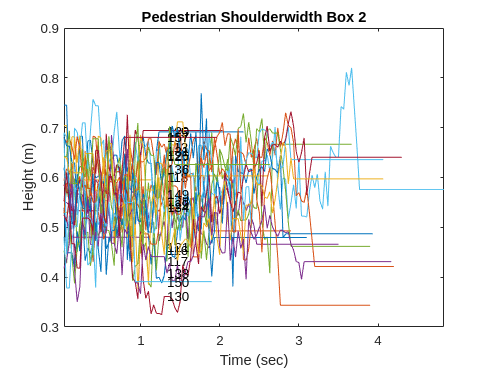



temparray2 = [];
temptime = (1:numel(AllShoulderWidth2(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllShoulderWidth2)
    str = string(AllId2(i));
    for x = 2:1:length(AllShoulderWidth2);
        temparray2(end+1) = AllShoulderWidth2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(4);
    plot(temptime2,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Shoulderwidth Box 2');
    xlim([1/30 (numel(AllShoulderWidth2(:,1))-1)/30]);
%     ylim([0.9 1.8])
    hold on;

    temparray2 = [];
end

## Sorting and plotting pedestrian speed by ID

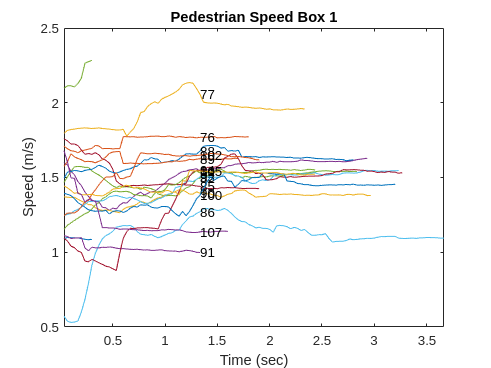

AllSpeed1 = zeros(1000,numel(AllId1));
b = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r), Person1.Id(i)))
           AllSpeed1(b,r) = Person1.Speed(i);
            b = b+1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        b = 1;
    end
end

AllSpeed1 = cat(1,AllId1,AllSpeed1);

AllSpeed2 = zeros(70,numel(AllId2));
j = 1;

for z = 1:1:numel(AllId2)
    for v = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,z), Person2.Id(v)))
            AllSpeed2(j,z) = Person2.Speed(v);
            j = j+1;
        end
    end
    if (isequal(v,numel(Person2.Id)))
        j = 1;
    end
end

AllSpeed2 = cat(1,AllId2,AllSpeed2);

for i = length(AllSpeed1):-1:1
    if (AllSpeed1(i,:) == 0)
       AllSpeed1(i,:) = [];
    end
end

for i = length(AllSpeed2):-1:1
    if (AllSpeed2(i,:) == 0)
        AllSpeed2(i,:) = [];
    end
end



% Deleting anyone with less than 40 structs or 1.33 seconds (different per bag)


% speedcounter1 = 0;
% for i = width(AllSpeed1):-1:1
%     for x = 2:1:length(AllSpeed1)
%         if (AllSpeed1(x,i) > 0)
%         speedcounter1 = speedcounter1 + 1;
%         end
%     end
%     if (speedcounter1 < numstruct)
%         AllSpeed1(:,i) = [];
%         AllId1(:,i) = [];
%     end
%     speedcounter1 = 0;
% end
% 
% speedcounter2 = 0;
% for i = width(AllSpeed2):-1:1
%     for x = 2:1:length(AllSpeed2)
%         if (AllSpeed2(x,i) > 0)
%         speedcounter2 = speedcounter2 + 1;
%         end
%     end
%     if (speedcounter2 < numstruct)
%         AllSpeed2(:,i) = [];
%         AllId2(:,i) = [];
%     end
%     speedcounter2 = 0;
% end




temparray = [];
temptime = (1:numel(AllSpeed1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllSpeed1)
    str = string(AllId1(i));
    for x = 2:1:length(AllSpeed1)
        temparray(end+1) = AllSpeed1(x,i);
    end

    y=temparray;
    y(y==0)=nan;
    figure(5);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Speed (m/s)');
    title('Pedestrian Speed Box 1');
    xlim([1/30 (numel(AllSpeed1(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray = [];
end

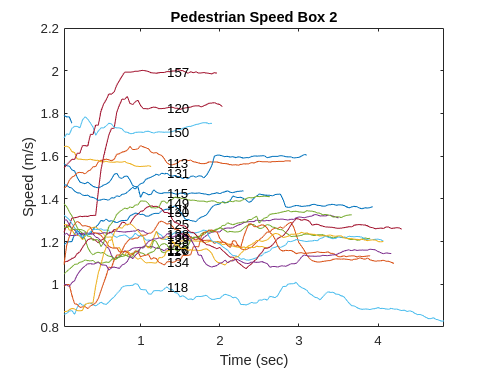




temparray2 = [];
temptime = (1:numel(AllSpeed2(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllSpeed2)
    str = string(AllId2(i));
    for x = 2:1:length(AllSpeed2)
        temparray2(end+1) = AllSpeed2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(6);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Speed (m/s)');
    title('Pedestrian Speed Box 2');
    xlim([1/30 (numel(AllSpeed2(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray2 = [];
end

## Sorting and plotting pedestrian atan(Vx/Vy) by ID

AllVelDirection1 = zeros(1000,numel(AllId1));
e = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r), Person1.Id(i)))
           AllVelDirection1(e,r) = Person1.VelDirection(i);
            e = e+1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        e = 1;
    end
end

AllVelDirection1 = cat(1,AllId1,AllVelDirection1);

AllVelDirection2 = zeros(70,numel(AllId2));
a = 1;

for z = 1:1:numel(AllId2)
    for v = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,z), Person2.Id(v)))
            AllVelDirection2(a,z) = Person2.VelDirection(v);
            a = a+1;
        end
    end
    if (isequal(v,numel(Person2.Id)))
        a = 1;
    end
end

AllVelDirection2 = cat(1,AllId2,AllVelDirection2);

for i = length(AllVelDirection1):-1:1
    if (AllVelDirection1(i,:) == 0)
       AllVelDirection1(i,:) = [];
    end
end

for i = length(AllVelDirection2):-1:1
    if (AllVelDirection2(i,:) == 0)
        AllVelDirection2(i,:) = [];
    end
end

## Sorting and plotting pedestrian Px & Py & Pz by ID in box 1

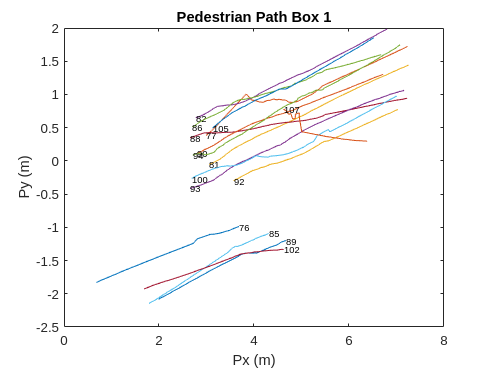

AllPx1 = zeros(1000,numel(AllId1));
q = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r),Person1.Id(i)))
            AllPx1(q,r) = Person1.Px(i);
            q = q + 1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        q = 1;
    end
end

AllPx1 = cat(1,AllId1,AllPx1);

AllPy1 = zeros(1000,numel(AllId1));
t = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r),Person1.Id(i)))
            AllPy1(t,r) = Person1.Py(i);
            t = t + 1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        t = 1;
    end
end

AllPy1 = cat(1,AllId1,AllPy1);

AllPo1 = zeros(1000,numel(AllId1));
m = 1;

for r = 1:1:numel(AllId1)
    for i = 1:1:numel(Person1.Id)
        if (isequal(AllId1(1,r),Person1.Id(i)))
            AllPo1(m,r) = Person1.Po(i);
            m = m + 1;
        end
    end
    if (isequal(i,numel(Person1.Id)))
        m = 1;
    end
end

AllPo1 = cat(1,AllId1,AllPo1);





for i = length(AllPx1):-1:1
    if (AllPx1(i,:) == 0)
        AllPx1(i,:) = [];
    end
end

for i = length(AllPy1):-1:1
    if (AllPy1(i,:) == 0)
        AllPy1(i,:) = [];
    end
end

for i = length(AllPo1):-1:1
    if (AllPo1(i,:) == 0)
        AllPo1(i,:) = [];
    end
end

% Deleting anyone with less than 40 structs or 1.33 seconds (different per bag)


speedcounter1 = 0;
for i = width(AllSpeed1):-1:1
    for x = 2:1:length(AllSpeed1)
        if (AllSpeed1(x,i) > 0)
            speedcounter1 = speedcounter1 + 1;
        end
    end
    if (speedcounter1 < numstruct)
        AllSpeed1(:,i) = [];
        AllHeight1(:,i) = [];
        AllShoulderWidth1(:,i) = [];
        AllPx1(:,i) = [];
        AllPy1(:,i) = [];
        AllPo1(:,i) = [];
        AllId1(:,i) = [];
    end
    speedcounter1 = 0;
end



Px = [];
Py = [];

for i = 1:1:width(AllId1)
    str = string(AllId1(i));
    for x = 2:1:length(AllPx1)
        Px(end+1) = AllPx1(x,i);
        Py(end+1) = AllPy1(x,i);
    end

    Pxn=Px;
    Pxn(Pxn==0)=nan;
    Pyn=Py;
    Pyn(Pyn==0)=nan;
    figure(7);
    plot(Pxn,Pyn)
    text(Pxn(1),Pyn(1), str, "FontSize", 7)
    xlabel('Px (m)'), ylabel('Py (m)');
    title('Pedestrian Path Box 1');
    hold on 

    Px = [];
    Py = [];
end

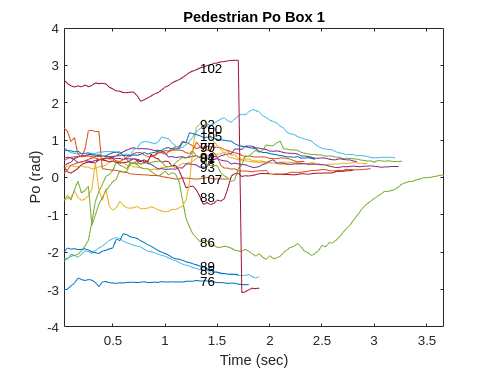








temparray = [];
temptime = (1:numel(AllPo1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllPo1)
    str = string(AllId1(i));
    for x = 2:1:length(AllPo1)
        temparray(end+1) = AllPo1(x,i);
    end

    y=temparray;
    y(y==0)=nan;
    figure(8);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Po (rad)');
    title('Pedestrian Po Box 1');
    xlim([1/30 (numel(AllPo1(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray = [];
end

## Deleting people with negative gradient path box 1 (leaving the people leaving box 1)

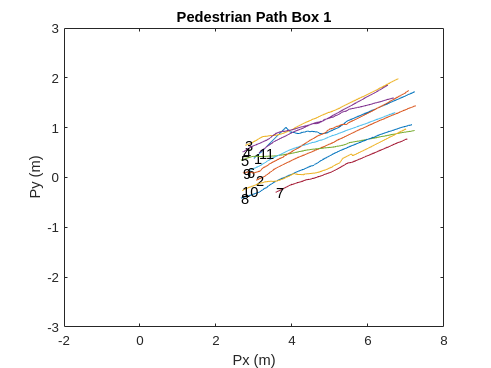

for i = width(AllPx1):-1:1
    
    rise = AllPy1(10,i) - AllPy1(2,i);

    if (AllPy1(10,i) < AllPy1(2,i))
        AllPx1(:,i) = [];
        AllPy1(:,i) = [];
        AllPo1(:,i) = [];
        AllId1(:,i) = [];
        AllHeight1(:,i) = [];
        AllShoulderWidth1(:,i) = [];
        AllSpeed1(:,i) = [];
    end
end








Px = [];
Py = [];

for i = 1:1:width(AllId1)
    str = string(AllId1Correspondence(i));
    for x = 2:1:length(AllPx1)
        Px(end+1) = AllPx1(x,i);
        Py(end+1) = AllPy1(x,i);
    end

    Pxn=Px;
    Pxn(Pxn==0)=nan;
    Pyn=Py;
    Pyn(Pyn==0)=nan;
    figure(9);
    plot(Pxn,Pyn)
    text(Pxn(1),Pyn(1), str, "FontSize", 11)
    xlabel('Px (m)'), ylabel('Py (m)');
    title('Pedestrian Path Box 1');
    xlim([-2 8]);
    ylim([-3 3]);
    hold on

    Px = [];
    Py = [];
end

## Sorting and plotting pedestrian Px & Py by ID in box 2

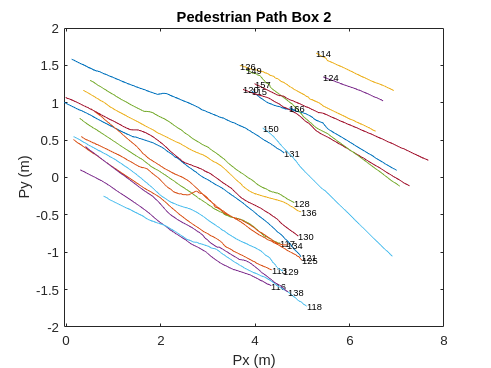

AllPx2 = zeros(1000,numel(AllId2));
k = 1;

for r = 1:1:numel(AllId2)
    for i = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,r),Person2.Id(i)))
            AllPx2(k,r) = Person2.Px(i);
            k = k + 1;
        end
    end
    if (isequal(i,numel(Person2.Id)))
        k = 1;
    end
end

AllPx2 = cat(1,AllId2,AllPx2);

AllPy2 = zeros(1000,numel(AllId2));
z = 1;

for r = 1:1:numel(AllId2)
    for i = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,r),Person2.Id(i)))
            AllPy2(z,r) = Person2.Py(i);
            z = z + 1;
        end
    end
    if (isequal(i,numel(Person2.Id)))
        z = 1;
    end
end

AllPy2 = cat(1,AllId2,AllPy2);

AllPo2 = zeros(1000,numel(AllId2));
b = 1;

for r = 1:1:numel(AllId2)
    for i = 1:1:numel(Person2.Id)
        if (isequal(AllId2(1,r),Person2.Id(i)))
            AllPo2(b,r) = Person2.Po(i);
            b = b + 1;
        end
    end
    if (isequal(i,numel(Person2.Id)))
        b = 1;
    end
end

AllPo2 = cat(1,AllId2,AllPo2);

for i = length(AllPx2):-1:1
    if (AllPx2(i,:) == 0)
        AllPx2(i,:) = [];
    end
end

for i = length(AllPy2):-1:1
    if (AllPy2(i,:) == 0)
        AllPy2(i,:) = [];
    end
end

for i = length(AllPo2):-1:1
    if (AllPo2(i,:) == 0)
        AllPo2(i,:) = [];
    end
end



% Deleting anyone with less than 40 structs or 1.33 seconds (different per bag)


speedcounter1 = 0;
for i = width(AllSpeed1):-1:1
    for x = 2:1:length(AllSpeed1)
        if (AllSpeed1(x,i) > 0)
            speedcounter1 = speedcounter1 + 1;
        end
    end
    if (speedcounter1 < numstruct)
        AllSpeed2(:,i) = [];
        AllHeight2(:,i) = [];
        AllShoulderWidth2(:,i) = [];
        AllPx2(:,i) = [];
        AllPy2(:,i) = [];
        AllPo2(:,i) = [];
        AllId2(:,i) = [];
    end
    speedcounter1 = 0;
end







Px2 = [];
Py2 = [];

for i = 1:1:width(AllId2)
    str = string(AllId2(i));
    for x = 2:1:length(AllPx2)
        Px2(end+1) = AllPx2(x,i);
        Py2(end+1) = AllPy2(x,i);
    end

    Pxn2=Px2;
    Pxn2(Pxn2==0)=nan;
    Pyn2=Py2;
    Pyn2(Pyn2==0)=nan;
    figure(10);

    plot(Pxn2,Pyn2)
    text(Pxn2(1),Pyn2(1),str, "FontSize", 7)
    xlabel('Px (m)'), ylabel('Py (m)');
    title('Pedestrian Path Box 2');
%     xlim([1 numel(AllHeight1(:,1))-1]);
%     ylim([0.8 1.6]);
    hold on 

    Px2 = [];
    Py2 = [];
end

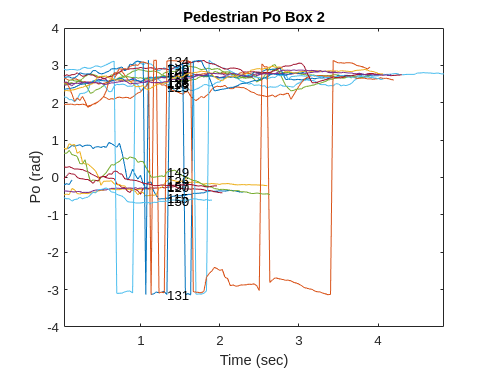








temparray = [];
temptime = (1:numel(AllPo2(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllPo2)
    str = string(AllId2(i));
    for x = 2:1:length(AllPo2)
        temparray(end+1) = AllPo2(x,i);
    end

    y=temparray;
    y(y==0)=nan;
    figure(11);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Po (rad)');
    title('Pedestrian Po Box 2');
    xlim([1/30 (numel(AllPo2(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray = [];
end

## Deleting people with negative gradient path box 2 (leaving the people entering box 2)

for i = width(AllPx2):-1:1
    
    rise = AllPy2(10,i) - AllPy2(2,i);

    if (AllPy2(20,i) < AllPy2(2,i))
        AllPx2(:,i) = [];
        AllPy2(:,i) = [];
        AllPo2(:,i) = [];
        AllId2(:,i) = [];
        AllHeight2(:,i) = [];
        AllShoulderWidth2(:,i) = [];
        AllSpeed2(:,i) = [];
    end
end


## Deleting the extra 2 people in box 2

AllPx2(:,12) = [];
AllPy2(:,12) = [];
AllPo2(:,12) = [];
AllId2(:,12) = [];
AllHeight2(:,12) = [];
AllShoulderWidth2(:,12) = [];
AllSpeed2(:,12) = [];

AllPx2(:,10) = [];
AllPy2(:,10) = [];
AllPo2(:,10) = [];
AllId2(:,10) = [];
AllHeight2(:,10) = [];
AllShoulderWidth2(:,10) = [];
AllSpeed2(:,10) = [];




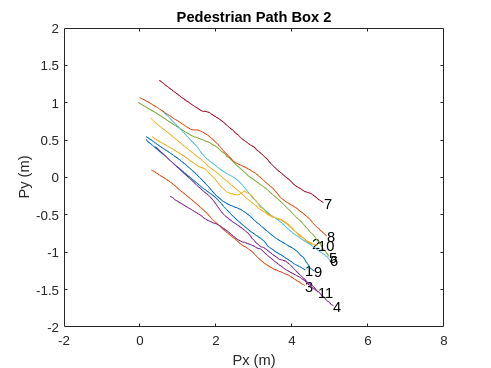



Px = [];
Py = [];

for i = 1:1:width(AllId2)
    str = string(AllId2Correspondence(i));
    for x = 2:1:length(AllPx2)
        Px(end+1) = AllPx2(x,i);
        Py(end+1) = AllPy2(x,i);
    end

    Pxn=Px;
    Pxn(Pxn==0)=nan;
    Pyn=Py;
    Pyn(Pyn==0)=nan;
    figure(12);
    plot(Pxn,Pyn)
    text(Pxn(1),Pyn(1), str, "FontSize", 11)
    xlabel('Px (m)'), ylabel('Py (m)');
    title('Pedestrian Path Box 2');
    xlim([-2 8]);
    ylim([-2 2]);
    hold on

    Px = [];
    Py = [];
end

## Deleting (particle filter prediction) last second of pedestrian data in box 1 and 2 for height and speed

Height

stepper = 0;

for i = width(AllId1):-1:1
    for x = length(AllHeight1):-1:1

        if (AllHeight1(x,i) ~= 0 && stepper < 30)
            AllHeight1(x,i) = 0;
            stepper = stepper + 1;
        end
    end
    stepper = 0;
end

stepper2 = 0;

for i = width(AllId2):-1:1
    for x = length(AllHeight2):-1:1

        if (AllHeight2(x,i) ~= 0 && stepper2 < 30)
            AllHeight2(x,i) = 0;
            stepper2 = stepper2 + 1;
        end
    end
    stepper2 = 0;
end

Speed

speedstepper = 0;

for i = width(AllId1):-1:1
    for x = length(AllSpeed1):-1:1

        if (AllSpeed1(x,i) ~= 0 && speedstepper < 30)
            AllSpeed1(x,i) = 0;
            speedstepper = speedstepper + 1;
        end
    end
    speedstepper = 0;
end

speedstepper2 = 0;

for i = width(AllId2):-1:1
    for x = length(AllSpeed2):-1:1

        if (AllSpeed2(x,i) ~= 0 && speedstepper2 < 30)
            AllSpeed2(x,i) = 0;
            speedstepper2 = speedstepper2 + 1;
        end
    end
    speedstepper2 = 0;
end

Shoulderwidth

shoulderstepper = 0;

for i = width(AllId1):-1:1
    for x = length(AllShoulderWidth1):-1:1

        if (AllShoulderWidth1(x,i) ~= 0 && shoulderstepper < 30)
            AllShoulderWidth1(x,i) = 0;
            shoulderstepper = shoulderstepper + 1;
        end
    end
    shoulderstepper = 0;
end

shoulderstepper2 = 0;

for i = width(AllId2):-1:1
    for x = length(AllShoulderWidth2):-1:1

        if (AllShoulderWidth2(x,i) ~= 0 && shoulderstepper2 < 30)
            AllShoulderWidth2(x,i) = 0;
            shoulderstepper2 = shoulderstepper2 + 1;
        end
    end
    shoulderstepper2 = 0;
end

## Replotting height, speed and shoulderwidth for box 1 and 2

Height

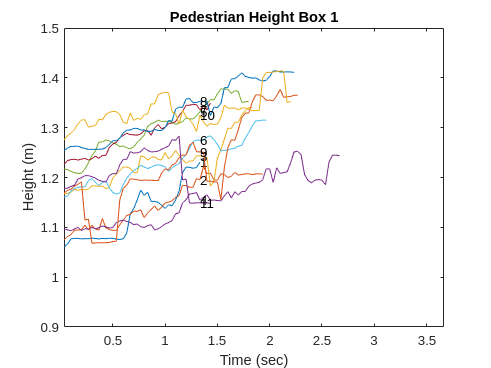

temparray1 = [];
temptime = (1:numel(AllHeight1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllHeight1)
    str = string(AllId1Correspondence(i));
    for x = 2:1:length(AllHeight1)
        temparray1(end+1) = AllHeight1(x,i);
    end

    y=temparray1;
    y(y==0)=nan;
    figure(13);
     plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Height Box 1');
    xlim([1/30 (numel(AllHeight1(:,1))-1)/30]);
    ylim([0.9 1.5]);
    hold on

    temparray1 = [];
end

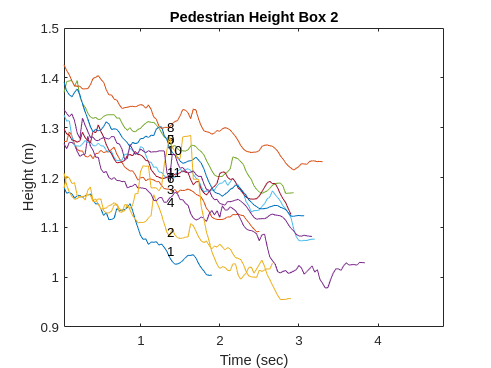


temparray2 = [];
temptime2 = (1:numel(AllHeight2(:,1))-1);
temptime2 = temptime2/30;

for i = 1:1:width(AllHeight2)
    str = string(AllId2Correspondence(i));
    for x = 2:1:length(AllHeight2)
        temparray2(end+1) = AllHeight2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(14);
    plot(temptime2,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Height Box 2');
    xlim([1/30 (numel(AllHeight2(:,1))-1)/30]);
    ylim([0.9 1.5]);
    hold on;

    temparray2 = [];
end

Shoulderwidth

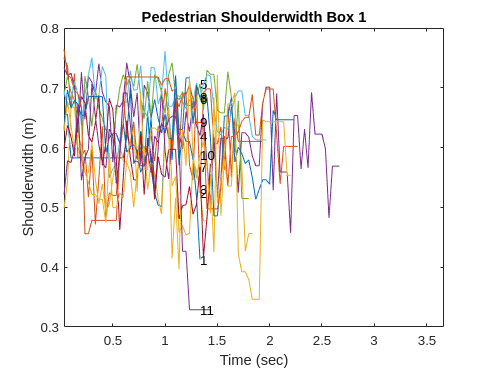

temparray1 = [];
temptime = (1:numel(AllShoulderWidth1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllShoulderWidth1)
    str = string(AllId1Correspondence(i));
    for x = 2:1:length(AllShoulderWidth1)
        temparray1(end+1) = AllShoulderWidth1(x,i);
    end

    y=temparray1;
    y(y==0)=nan;
    figure(15);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Shoulderwidth (m)');
    title('Pedestrian Shoulderwidth Box 1');
    xlim([1/30 (numel(AllShoulderWidth1(:,1))-1)/30]);
%     ylim([0.9 1.7])
    hold on;

    temparray1 = [];
end

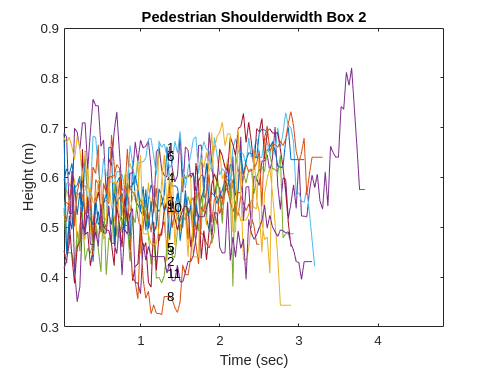



temparray2 = [];
temptime = (1:numel(AllShoulderWidth2(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllShoulderWidth2)
    str = string(AllId2Correspondence(i));
    for x = 2:1:length(AllShoulderWidth2);
        temparray2(end+1) = AllShoulderWidth2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(16);
    plot(temptime2,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Height (m)');
    title('Pedestrian Shoulderwidth Box 2');
    xlim([1/30 (numel(AllShoulderWidth2(:,1))-1)/30]);
%     ylim([0.9 1.8])
    hold on;

    temparray2 = [];
end

Speed

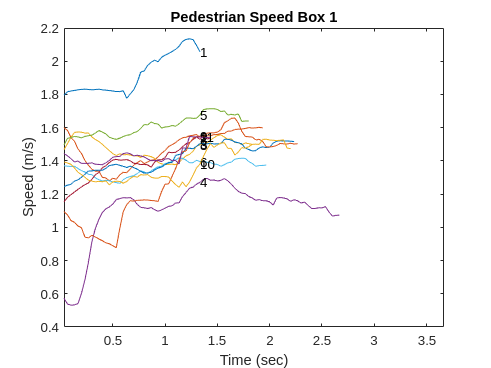


temparray = [];
temptime = (1:numel(AllSpeed1(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllSpeed1)
    str = string(AllId1Correspondence(i));
    for x = 2:1:length(AllSpeed1)
        temparray(end+1) = AllSpeed1(x,i);
    end

    y=temparray;
    y(y==0)=nan;
    figure(17);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Speed (m/s)');
    title('Pedestrian Speed Box 1');
    xlim([1/30 (numel(AllSpeed1(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray = [];
end

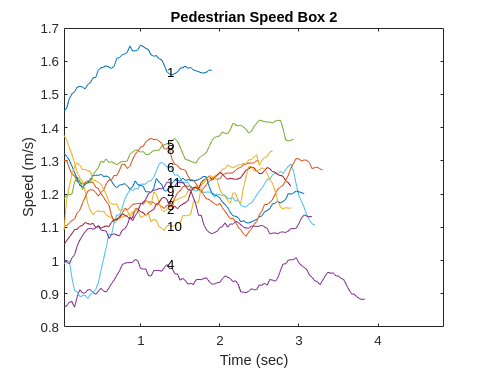




temparray2 = [];
temptime = (1:numel(AllSpeed2(:,1))-1);
temptime = temptime/30;

for i = 1:1:width(AllSpeed2)
    str = string(AllId2Correspondence(i));
    for x = 2:1:length(AllSpeed2)
        temparray2(end+1) = AllSpeed2(x,i);
    end

    y=temparray2;
    y(y==0)=nan;
    figure(18);
    plot(temptime,y)
    text(temptime(40),y(40), str)
    xlabel('Time (sec)'), ylabel('Speed (m/s)');
    title('Pedestrian Speed Box 2');
    xlim([1/30 (numel(AllSpeed2(:,1))-1)/30]);
%     ylim([1 1.8])
    hold on;

    temparray2 = [];
end

## Statistical analysis: Calculating mean, standard deviation of data

For height

Column = [];
HeightAverage1 = [];
HeightDeviation1 = [];

heightjumper1 = 0;

for r = 1:1:width(AllHeight1)
    for i = 2:1:length(AllHeight1)
        %     for i = 2:1:30
        %         if (AllHeight1(i,r) ~= 0 && heightjumper1 < 40)
        if (AllHeight1(i,r) ~= 0)
            Column(end+1) = AllHeight1(i,r);
            heightjumper1 = heightjumper1 + 1;
        end
    end
    heightjumper1 = 0;
    HeightAverage1(end+1) = mean(Column);
    HeightDeviation1(end+1) = std(Column);
    Column = [];
end

Column = [];
HeightAverage2 = [];
HeightDeviation2 = [];

heightjumper2 = 0;

for r = 1:1:width(AllHeight2)
    for i = length(AllHeight2):-1:2
        %     for i = 30:1:60
        %         if (AllHeight2(i,r) ~= 0 && heightjumper2 < 45)
        if (AllHeight2(i,r) ~= 0)
            Column(end+1) = AllHeight2(i,r);
            heightjumper2 = heightjumper2 + 1;
        end
    end
    heightjumper2 = 0;
    HeightAverage2(end+1) = mean(Column);
    HeightDeviation2(end+1) = std(Column);
    Column = [];
end

For shoulder width

Column = [];
ShoulderWidthAverage1 = [];
ShoulderWidthDeviation1 = [];

shoulderjumper1 = 0;

for r = 1:1:width(AllShoulderWidth1)
    for i = 2:1:length(AllShoulderWidth1)
        %      for i = 2:1:30
        %         if (AllShoulderWidth1(i,r) ~= 0 && shoulderjumper1 < 30)
        if (AllShoulderWidth1(i,r) ~= 0)
            Column(end+1) = AllShoulderWidth1(i,r);
            shoulderjumper1 = shoulderjumper1 + 1;
        end
    end
    shoulderjumper1 = 0;
    ShoulderWidthAverage1(end+1) = mean(Column);
    ShoulderWidthDeviation1(end+1) = std(Column);
    Column = [];
end

Column = [];
ShoulderWidthAverage2 = [];
ShoulderWidthDeviation2 = [];

shoulderjumper2 = 0;

for r = 1:1:width(AllShoulderWidth2)
    for i = 2:1:length(AllShoulderWidth2)
        %      for i = 30:1:60
        %         if (AllShoulderWidth2(i,r) ~= 0 && shoulderjumper2 < 30)
        if (AllShoulderWidth2(i,r) ~= 0)
            Column(end+1) = AllShoulderWidth2(i,r);
            shoulderjumper2 = shoulderjumper2 + 1;
        end
    end
    shoulderjumper2 = 0;
    ShoulderWidthAverage2(end+1) = mean(Column);
    ShoulderWidthDeviation2(end+1) = std(Column);
    Column = [];
end

For speed

Column = [];
SpeedAverage1 = [];
SpeedDeviation1 = [];

speedjumper1 = 0;

for r = 1:1:width(AllSpeed1)
    %     for i = 2:1:30
    for i = 2:1:length(AllSpeed1)
        %         if (AllSpeed1(i,r) ~= 0 && speedjumper1 < 30)
        if (AllSpeed1(i,r) ~= 0)
            Column(end+1) = AllSpeed1(i,r);
            speedjumper1 = speedjumper1 + 1;
        end
    end
    speedjumper1 = 0;
    SpeedAverage1(end+1) = mean(Column);
    SpeedDeviation1(end+1) = std(Column);
    Column = [];
end

Column = [];
SpeedAverage2 = [];
SpeedDeviation2 = [];

speedjumper2 = 0;

for r = 1:1:width(AllSpeed2)

    %     for i = 30:1:60
    for i = length(AllSpeed2):-1:2
        %         if (AllSpeed2(i,r) ~= 0 && speedjumper2 < 30)
        if (AllSpeed2(i,r) ~= 0)
            Column(end+1) = AllSpeed2(i,r);
            speedjumper2 = speedjumper2 + 1;
        end
    end
    speedjumper2 = 0;
    SpeedAverage2(end+1) = mean(Column);
    SpeedDeviation2(end+1) = std(Column);
    Column = [];
end

## Plotting histograms

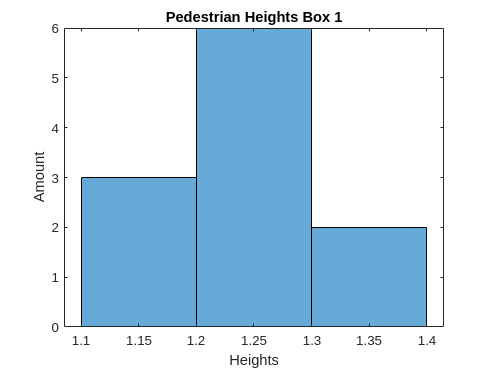

figure(19)
histogram(HeightAverage1)
xlabel('Heights'), ylabel('Amount')
title('Pedestrian Heights Box 1')

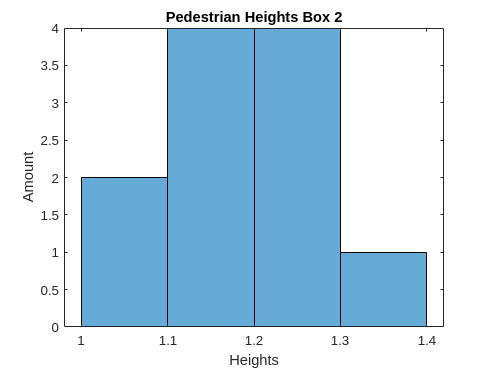

% xlim([0.9 1.4]);

% [1:0.1:1.4]

figure(20)
histogram(HeightAverage2)
xlabel('Heights'), ylabel('Amount')
title('Pedestrian Heights Box 2')

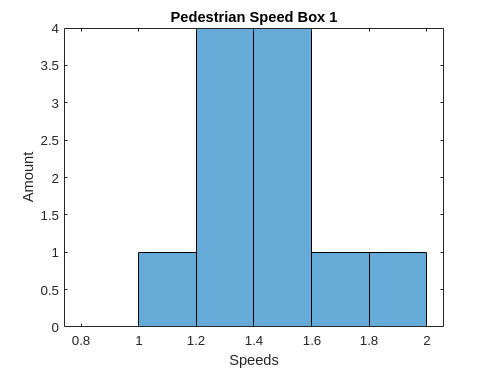

% xlim([0.9 1.4]);

figure(21)
histogram(SpeedAverage1, [0.8:0.2:2.1])
xlabel('Speeds'), ylabel('Amount')
title('Pedestrian Speed Box 1')

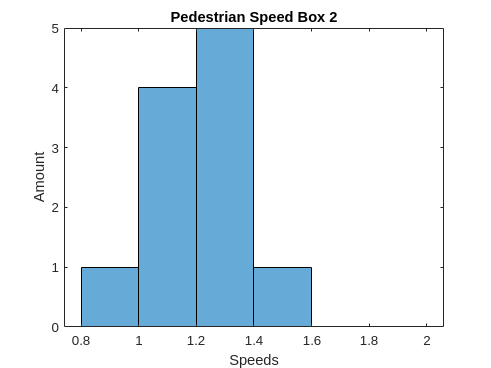

% xlim([0.8 2.1]);

% [0.8:0.2:2.1]

figure(22)
histogram(SpeedAverage2, [0.8:0.2:2.1])
xlabel('Speeds'), ylabel('Amount')
title('Pedestrian Speed Box 2')

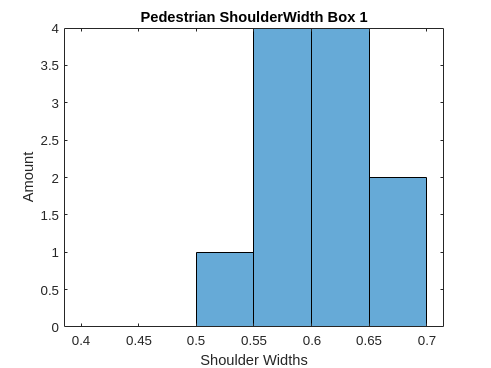

% xlim([0.8 2.1]);

figure(23)
histogram(ShoulderWidthAverage1, [0.4:0.05:0.7])
xlabel('Shoulder Widths'), ylabel('Amount')
title('Pedestrian ShoulderWidth Box 1')

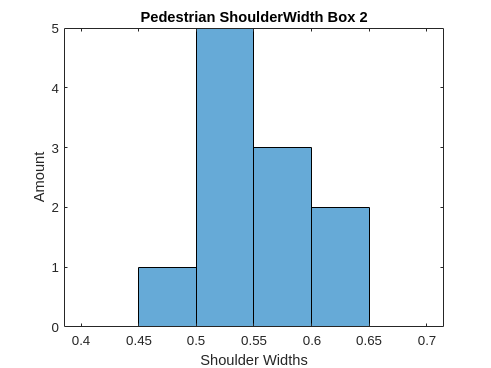

% xlim([0.4 0.7]);

% [0.4:0.05:0.7]

figure(24)
histogram(ShoulderWidthAverage2, [0.4:0.05:0.7])
xlabel('Shoulder Widths'), ylabel('Amount')
title('Pedestrian ShoulderWidth Box 2')

% xlim([0.4 0.7]);

## Probability Analysis

% speeddif = []
% shoulderdif
% heightdif

% [firstsordered, firstsortorder] = unique(SpeedAverage1);
% secondsorted = AllId1(firstsortorder);

% count = 0;
% 
% for i = 1:1:length(AllId1)
%     for  k = 1:1:length(AllId2)
%         speeddif(k,i) = abs(SpeedAverage1(i) - SpeedAverage2(k));
%         shoulderdif(k,i) = abs(ShoulderWidthAverage1(i) - ShoulderWidthAverage2(k));
%         heightdif(k,i) = abs(HeightAverage1(i) - HeightAverage2(k));  
%     end
% end
% 
% smallestvalue = min(speeddif);
% 
% AllSpeedDif1 = cat(1,AllId1,speeddif);



% mu = [1 -1];
% Sigma = [0.9 0.4; 0.4 0.3];
% 
% 
% y = mvnpdf(X,mu,Sigma);
% 
% scatter3(X(:,1),X(:,2),y)
% xlabel('X1')
% ylabel('X2')
% zlabel('Probability Density')

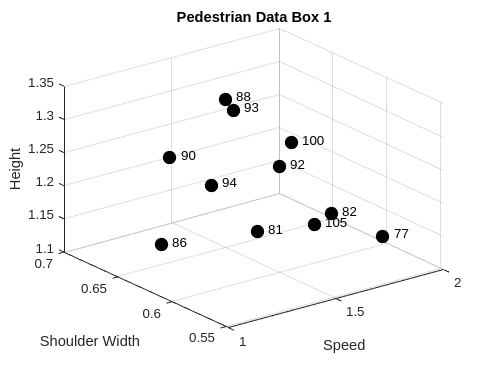

str = string(AllId1);
sz = 100;

figure(25)
scatter3(SpeedAverage1,ShoulderWidthAverage1, HeightAverage1, 'black', 'filled', 'o', 'SizeData', 100)
xlabel('Speed'), ylabel('Shoulder Width'), zlabel('Height')
title('Pedestrian Data Box 1')
text(SpeedAverage1+0.05, ShoulderWidthAverage1, HeightAverage1, str)

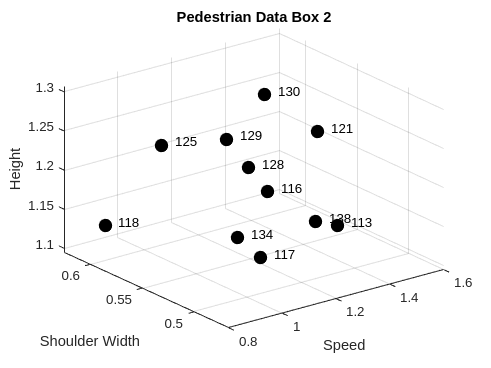


str = string(AllId2);

figure(26)
scatter3(SpeedAverage2,ShoulderWidthAverage2, HeightAverage2, 'black', 'filled', 'o', 'SizeData', 100)
xlabel('Speed'), ylabel('Shoulder Width'), zlabel('Height')
title('Pedestrian Data Box 2')
text(SpeedAverage2+0.05, ShoulderWidthAverage2, HeightAverage2, str)


% mu = mean(SpeedAverage2);
% sigma = std(SpeedAverage2);
% pd = makedist('Normal','mu',mu,'sigma',sigma);
% x = SpeedAverage2;
% y = pdf(pd,x)
% scatter(x,y)

% x = SpeedAverage1';
% pd = fitdist(x,'Normal');
% x = [0.9:0.1:2.1];
% y = normpdf(x,mean(SpeedAverage1),std(SpeedAverage1));
% plot(x,y)

% x = SpeedAverage2';
% pd = fitdist(x,'Normal');
% x = [0.7:0.1:1.8];
% y = normpdf(x,mean(SpeedAverage2),std(SpeedAverage2));
% plot(x,y)



% [f,xi] = ksdensity(x);
% plot(xi,f);

% mu = [1 -1];
% Sigma = [0.9 0.4; 0.4 0.3];
% X = SpeedAverage1;
% 
% y = mvnpdf(X,mu,Sigma);
% 
% scatter3(SpeedAverage1,ShoulderWidthAverage1,y)
% xlabel('X1');
% ylabel('X2');
% zlabel('Probability Density');

## Pedestrian Speed Unique Functions

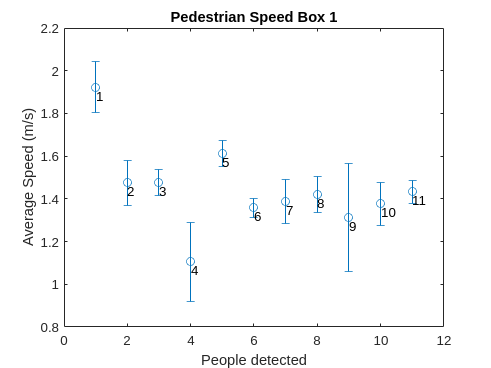

str = string(AllId1Correspondence);

x = 1:numel(AllId1);
figure(27)
% scatter(x,SpeedAverage1)
errorbar(SpeedAverage1, SpeedDeviation1, 'o')
ylabel('Average Speed (m/s)'), xlabel('People detected')
title('Pedestrian Speed Box 1')
text(x, SpeedAverage1-0.04, str)

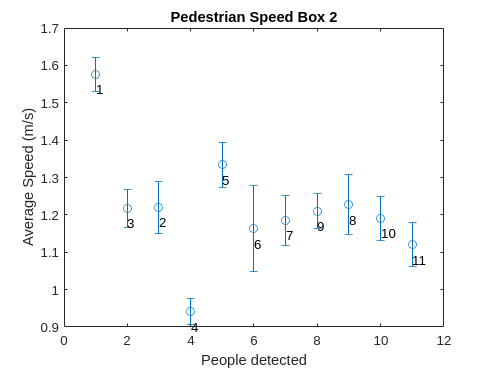


str = string(AllId2Correspondence);
x = 1:numel(AllId2);
figure(28)
% scatter(x,SpeedAverage2)
errorbar(SpeedAverage2, SpeedDeviation2, 'o')
ylabel('Average Speed (m/s)'), xlabel('People detected')
title('Pedestrian Speed Box 2')
text(x, SpeedAverage2-0.04, str)

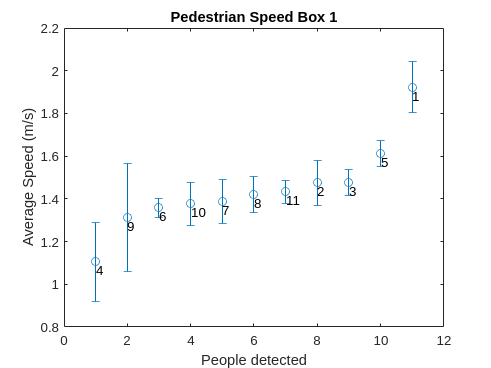


[firstsordered, firstsortorder] = unique(SpeedAverage1);
secondsorted = AllId1Correspondence(firstsortorder);
SpeedDeviation1 = SpeedDeviation1(firstsortorder);

str = string(secondsorted);
x = 1:numel(AllId1);
figure(29)
% scatter(x,firstsordered)
errorbar(firstsordered, SpeedDeviation1, 'o')
ylabel('Average Speed (m/s)'), xlabel('People detected')
title('Pedestrian Speed Box 1')
text(x, firstsordered-0.04, str)

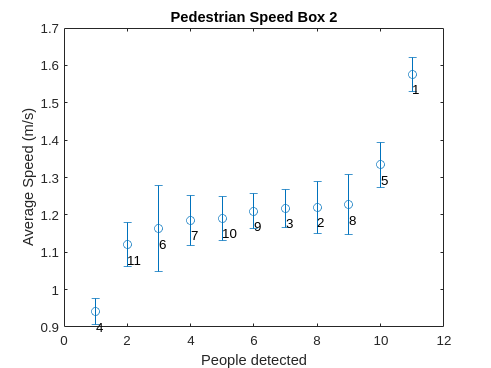


[firstsordered, firstsortorder] = unique(SpeedAverage2);
secondsorted = AllId2Correspondence(firstsortorder);
SpeedDeviation2 = SpeedDeviation2(firstsortorder);

str = string(secondsorted);
x = 1:numel(AllId2);
figure(30)
% scatter(x,firstsordered)
errorbar(firstsordered, SpeedDeviation2, 'o')
ylabel('Average Speed (m/s)'), xlabel('People detected')
title('Pedestrian Speed Box 2')
text(x, firstsordered-0.04, str)

## Pedestrian Shoulderwidth Unique Functions

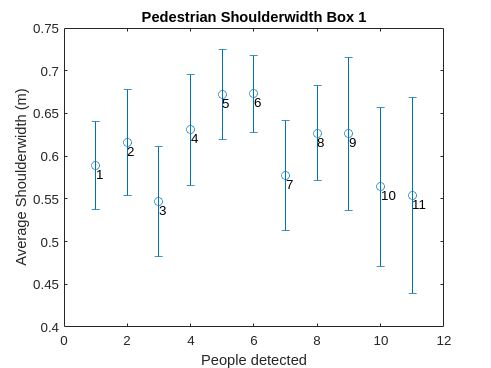

str = string(AllId1Correspondence);

x = 1:numel(AllId1);
figure(31)
% scatter(x,ShoulderWidthAverage1)
errorbar(ShoulderWidthAverage1, ShoulderWidthDeviation1, 'o')
ylabel('Average Shoulderwidth (m)'), xlabel('People detected')
title('Pedestrian Shoulderwidth Box 1')
text(x, ShoulderWidthAverage1-0.01, str)

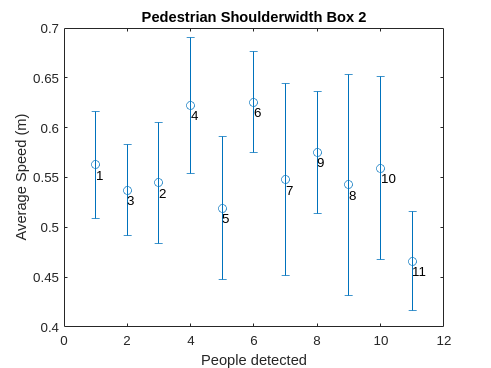


str = string(AllId2Correspondence);
x = 1:numel(AllId2);
figure(32)
% scatter(x,ShoulderWidthAverage2)
errorbar(ShoulderWidthAverage2, ShoulderWidthDeviation2, 'o')
ylabel('Average Speed (m)'), xlabel('People detected')
title('Pedestrian Shoulderwidth Box 2')
text(x, ShoulderWidthAverage2-0.01, str)

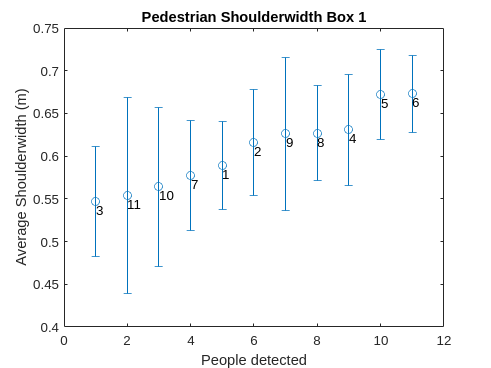


[firstsordered, firstsortorder] = unique(ShoulderWidthAverage1);
secondsorted = AllId1Correspondence(firstsortorder);
ShoulderWidthDeviation1 = ShoulderWidthDeviation1(firstsortorder);

str = string(secondsorted);
x = 1:numel(AllId1);
figure(33)
% scatter(x,firstsordered)
errorbar(firstsordered, ShoulderWidthDeviation1, 'o')
ylabel('Average Shoulderwidth (m)'), xlabel('People detected')
title('Pedestrian Shoulderwidth Box 1')
text(x, firstsordered-0.01, str)

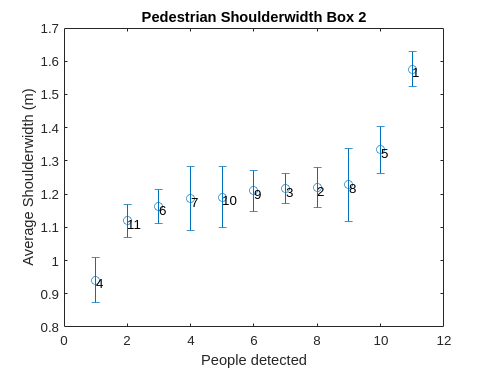


[firstsordered, firstsortorder] = unique(SpeedAverage2);
secondsorted = AllId2Correspondence(firstsortorder);
ShoulderWidthDeviation2 = ShoulderWidthDeviation2(firstsortorder);

str = string(secondsorted);
x = 1:numel(AllId2);
figure(34)
% scatter(x,firstsordered)
errorbar(firstsordered, ShoulderWidthDeviation2, 'o')
ylabel('Average Shoulderwidth (m)'), xlabel('People detected')
title('Pedestrian Shoulderwidth Box 2')
text(x, firstsordered-0.01, str)

## Pedestrian Height Unique Functions

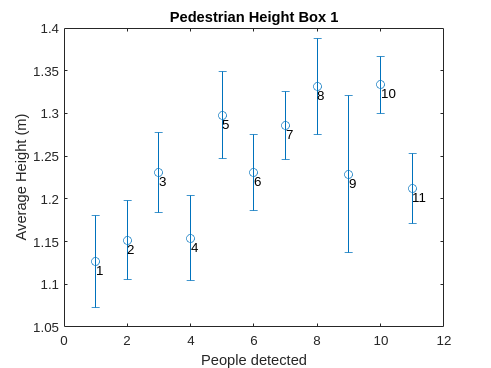

str = string(AllId1Correspondence);

x = 1:numel(AllId1);
figure(35)
% scatter(x,HeightAverage1)
errorbar(HeightAverage1,HeightDeviation1, 'o')
ylabel('Average Height (m)'), xlabel('People detected')
title('Pedestrian Height Box 1')
text(x, HeightAverage1-0.01, str)

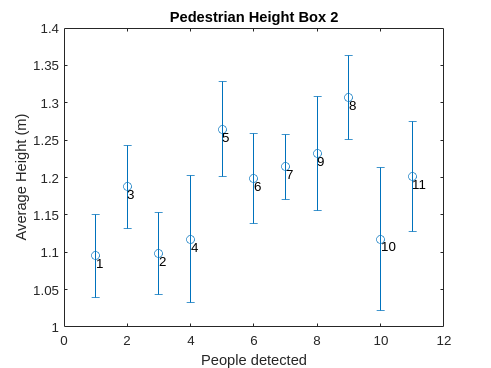


str = string(AllId2Correspondence);
x = 1:numel(AllId2);
figure(36)
% scatter(x,HeightAverage2)
errorbar(HeightAverage2,HeightDeviation2, 'o')
ylabel('Average Height (m)'), xlabel('People detected')
title('Pedestrian Height Box 2')
text(x, HeightAverage2-0.01, str)

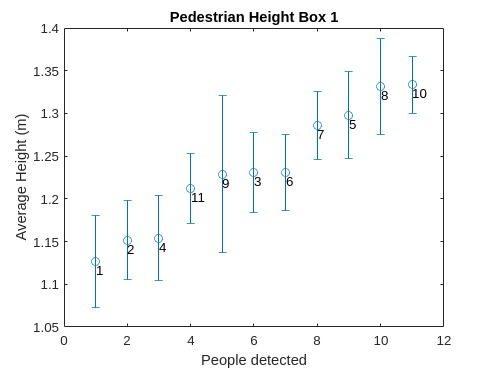


[firstsordered, firstsortorder] = unique(HeightAverage1);
secondsorted = AllId1Correspondence(firstsortorder);
HeightDeviation1 = HeightDeviation1(firstsortorder);

str = string(secondsorted);
x = 1:11;
figure(37)
% scatter(x,firstsordered)
errorbar(firstsordered,HeightDeviation1, 'o')
ylabel('Average Height (m)'), xlabel('People detected')
title('Pedestrian Height Box 1')
text(x, firstsordered-0.01, str)

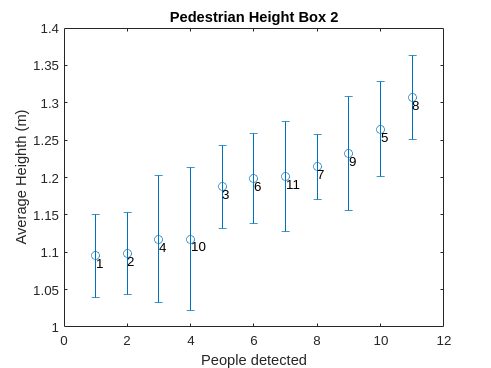


[firstsordered, firstsortorder] = unique(HeightAverage2);
secondsorted = AllId2Correspondence(firstsortorder);
HeightDeviation2 = HeightDeviation2(firstsortorder);

str = string(secondsorted);
x = 1:11;
figure(38)
% scatter(x,firstsordered)
errorbar(firstsordered,HeightDeviation2, 'o')
ylabel('Average Heighth (m)'), xlabel('People detected')
title('Pedestrian Height Box 2')
text(x, firstsordered-0.01, str)

## Normal probability plots

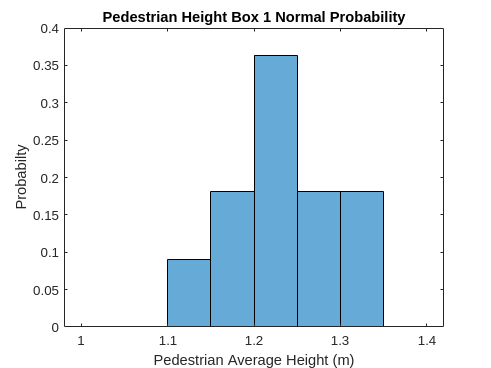

figure(39)
histogram(HeightAverage1, [1:0.05:1.4], 'Normalization', 'probability')
ylim([0 0.4]);
xlabel('Pedestrian Average Height (m)'), ylabel('Probabilty')
title('Pedestrian Height Box 1 Normal Probability')

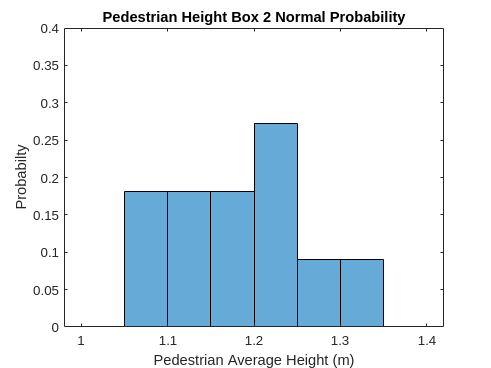


figure(40)
histogram(HeightAverage2, [1:0.05:1.4], 'Normalization', 'probability')
ylim([0 0.4]);
xlabel('Pedestrian Average Height (m)'), ylabel('Probabilty')
title('Pedestrian Height Box 2 Normal Probability')

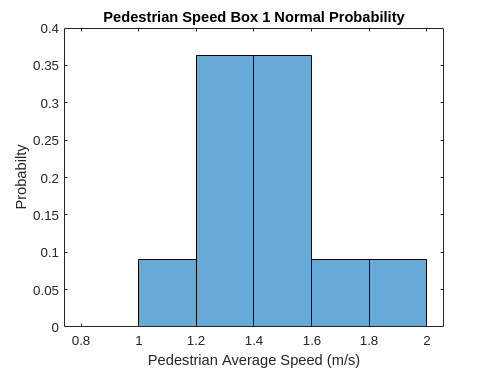


figure(41)
histogram(SpeedAverage1, [0.8:0.2:2.1], 'Normalization', 'probability')
xlabel('Pedestrian Average Speed (m/s)'), ylabel('Probabilty')
title('Pedestrian Speed Box 1 Normal Probability')

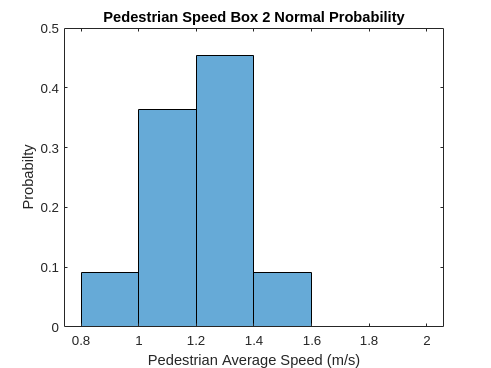


figure(42)
histogram(SpeedAverage2, [0.8:0.2:2.1], 'Normalization', 'probability')
xlabel('Pedestrian Average Speed (m/s)'), ylabel('Probabilty')
title('Pedestrian Speed Box 2 Normal Probability')

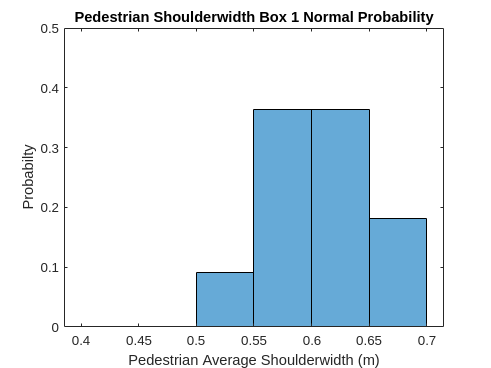


figure(43)
histogram(ShoulderWidthAverage1, [0.4:0.05:0.7], 'Normalization', 'probability')
ylim([0 0.5]);
xlabel('Pedestrian Average Shoulderwidth (m)'), ylabel('Probabilty')
title('Pedestrian Shoulderwidth Box 1 Normal Probability')

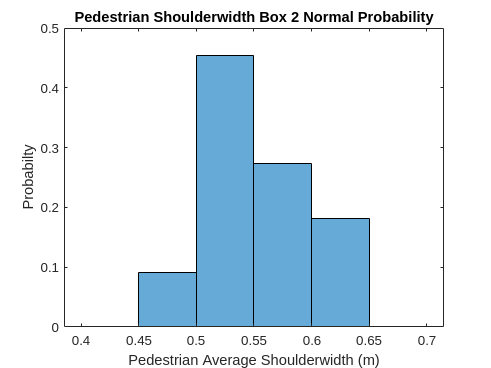


figure(44)
histogram(ShoulderWidthAverage2, [0.4:0.05:0.7], 'Normalization', 'probability')
xlabel('Pedestrian Average Shoulderwidth (m)'), ylabel('Probabilty')
title('Pedestrian Shoulderwidth Box 2 Normal Probability')

## Cumulative probability plots

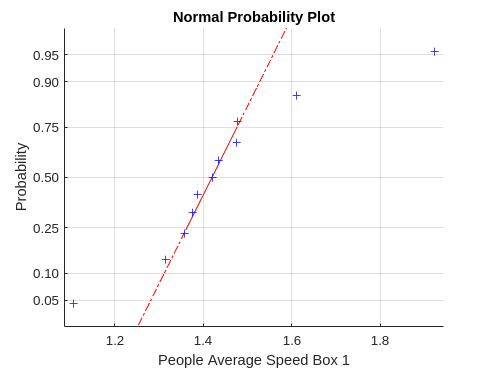


figure(45)
normplot(SpeedAverage1)
xlabel('People Average Speed Box 1');

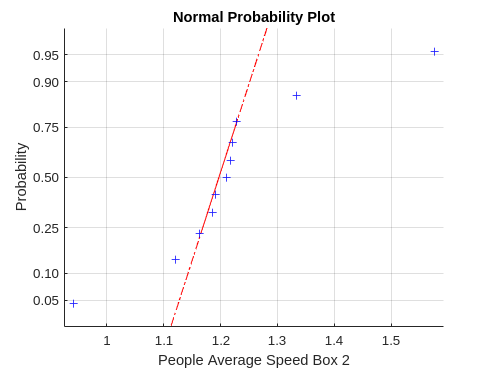


figure(46)
normplot(SpeedAverage2)
xlabel('People Average Speed Box 2');

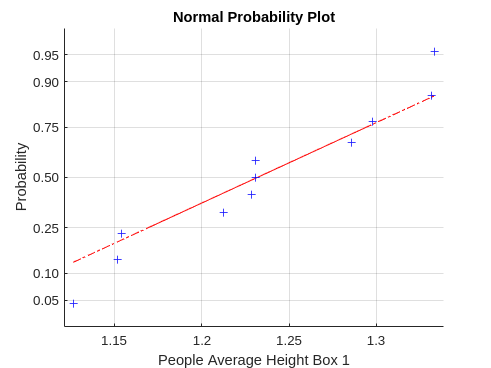


figure(47)
normplot(HeightAverage1)
xlabel('People Average Height Box 1');

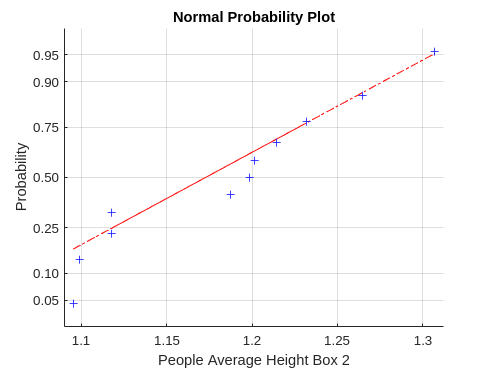


figure(48)
normplot(HeightAverage2)
xlabel('People Average Height Box 2');

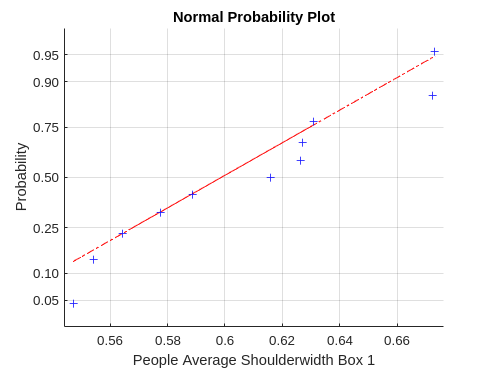


figure(49)
normplot(ShoulderWidthAverage1)
xlabel('People Average Shoulderwidth Box 1');

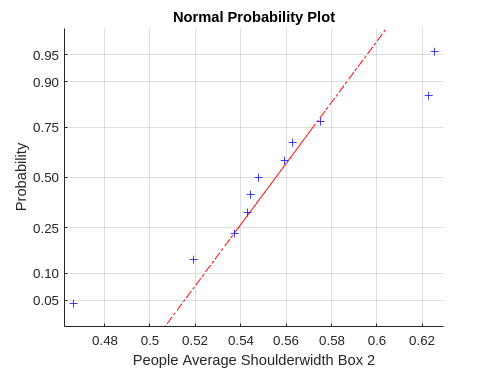


figure(50)
normplot(ShoulderWidthAverage2)
xlabel('People Average Shoulderwidth Box 2');

## Bivariate Probability Density Functions

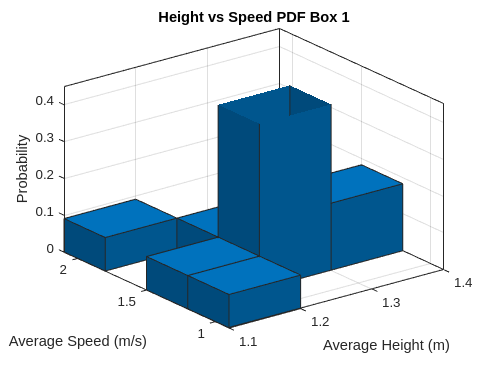


X = HeightAverage1; % random variables.
Y = SpeedAverage1;
% 
% x_axis = 1:.1:1.4; % Define edges of bins for x axis. Column vector
% y_axis = 0.8:.1:2.1; % Same for y axis
% 
% // Compute and plot pdf
figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Height vs Speed PDF Box 1')
xlabel('Average Height (m)'); ylabel('Average Speed (m/s)'); zlabel('Probability');

% 
% // Compute and plot cdf
% figure
% histogram2(X, Y, 'Normalization', 'cdf')


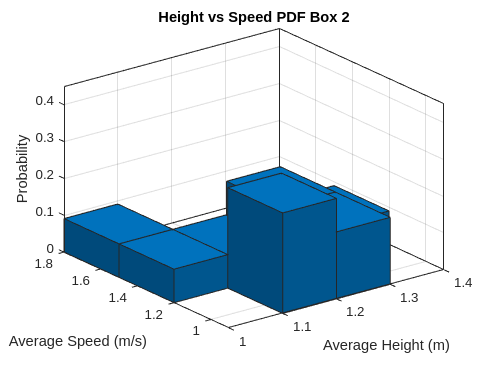


X = HeightAverage2; % random variables.
Y = SpeedAverage2;

% x_axis = 1:.1:1.4; % Define edges of bins for x axis. Column vector
% y_axis = 0.8:.1:2.1; % Same for y axis
% 
% // Compute and plot pdf
% figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Height vs Speed PDF Box 2')
xlabel('Average Height (m)'); ylabel('Average Speed (m/s)'); zlabel('Probability');

% 
% %// Compute and plot cdf
% figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'cdf')


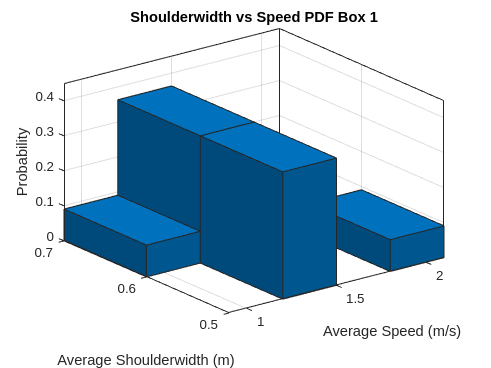

X = SpeedAverage1; 
Y = ShoulderWidthAverage1;

x_axis = 0.8:0.2:2.2; % Define edges of bins for x axis. Column vector
y_axis = 0.4:0.05:0.7; % Same for y axis

figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Shoulderwidth vs Speed PDF Box 1')
xlabel('Average Speed (m/s)'); ylabel('Average Shoulderwidth (m)'); zlabel('Probability');


% figure
% histogram2(X, Y, 'Normalization', 'cdf')

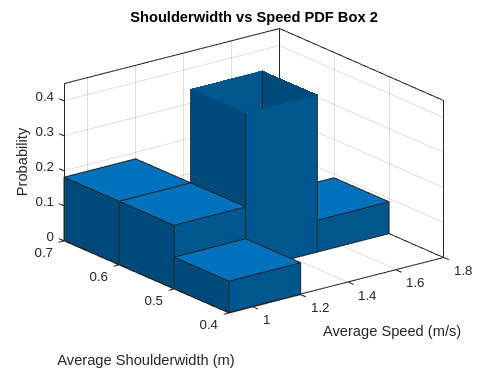

X = SpeedAverage2; 
Y = ShoulderWidthAverage2;

x_axis = 0.4:0.2:2.2; % Define edges of bins for x axis. Column vector
y_axis = 0.4:0.05:0.7; % Same for y axis
% 
% // Compute and plot pdf
figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Shoulderwidth vs Speed PDF Box 2')
xlabel('Average Speed (m/s)'); ylabel('Average Shoulderwidth (m)'); zlabel('Probability');

 

% figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'cdf')


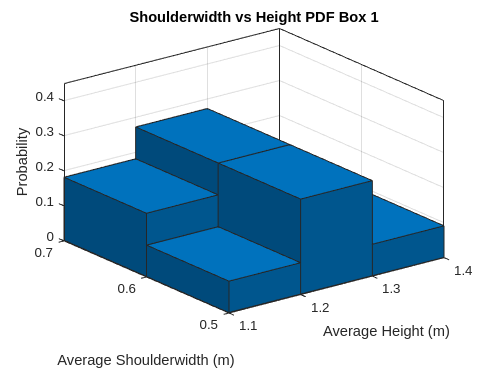


X = HeightAverage1; 
Y = ShoulderWidthAverage1;

x_axis = 0.4:0.2:2.2; % Define edges of bins for x axis. Column vector
y_axis = 0.4:0.05:0.7; % Same for y axis

figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Shoulderwidth vs Height PDF Box 1')
xlabel('Average Height (m)'); ylabel('Average Shoulderwidth (m)'); zlabel('Probability');


% figure
% histogram2(X, Y, 'Normalization', 'cdf')

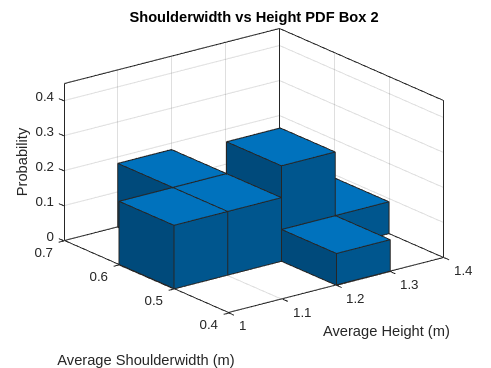

X = HeightAverage2; 
Y = ShoulderWidthAverage2;

x_axis = 0.4:0.2:2.2; % Define edges of bins for x axis. Column vector
y_axis = 0.4:0.05:0.7; % Same for y axis
% 
% // Compute and plot pdf
figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'pdf')
histogram2(X, Y, 'Normalization', 'probability')
zlim([0 0.45]);
title('Shoulderwidth vs Height PDF Box 2')
xlabel('Average Height (m)'); ylabel('Average Shoulderwidth (m)'); zlabel('Probability');

 

% figure
% histogram2(X, Y, x_axis, y_axis, 'Normalization', 'cdf')